## 核融合エネルギー工学レポート0530

### 問1(5)

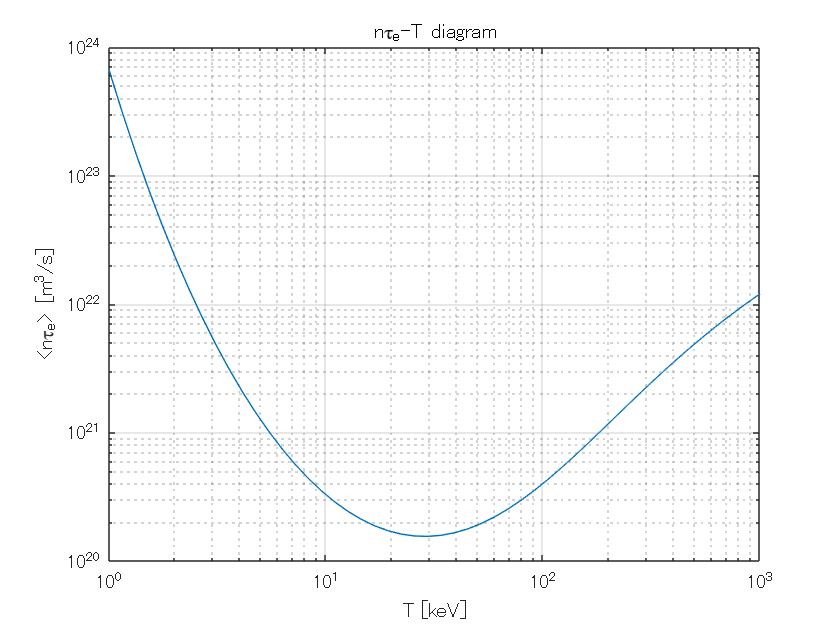

x1 =-48.9580809680824;
x2 = 18.1155080330636;
x3 =895.149425658926;
x4 =135.888636700177;
x5 = 0.366290140624939;
ev = 1.60e-19; %[J/ev]

T = logspace(0,3); %[keV]
kT = T.*10^3*ev; %[J]
E = 3.52e6*ev; %[J]




sigma_nu = exp(x1-x2./T.^x5+x3./(T+x4)); %[m^3/s]

n_tau = 12*kT./(sigma_nu.*E);

figure;
loglog(T,n_tau)
grid on

xlabel('T [keV]')
ylabel('<n\tau_e> [m^3/s]')
title('n\tau_e-T diagram')